## Name: Cody Gorman

## Student Number: c3378568

clc;
close all;
clear all;

## 1a

f = @(x) -abs(x)*x;

f(-4)

ans = 16

## 1b

%x = [x1;x2];
x = [4;-5];
g(x)

ans =    -61
    25


## 1c

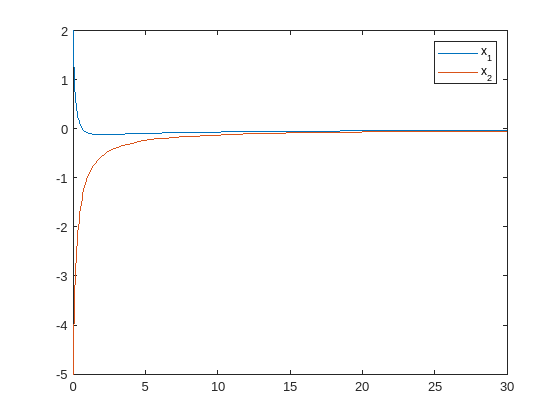

x0 = [2;-5];
tspan = [0 30];

[t,x] = ode45(@dx,tspan,x0);
plot(t,x(:,1),t,x(:,2));
legend('x_1','x_2');

## 1d

[ut,ux] = ode45(@dux,tspan,x0);
plot(ut,ux(:,1),ut,ux(:,2));
legend('x_1','x_2');

## 1e

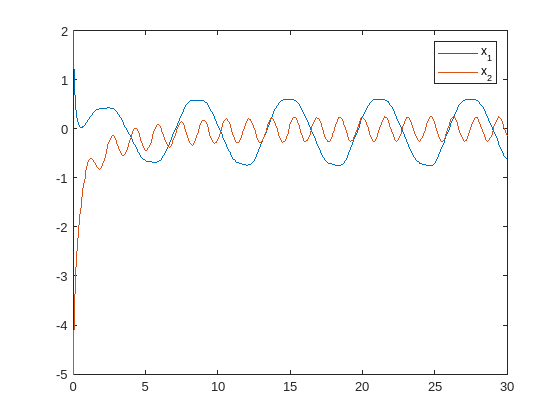

[et,ex] = ode45(@dex,tspan,x0);
plot(et,ex(:,1),et,ex(:,2));
legend('x_1','x_2');

function gx = g(x)
    gx = [-(x(1)^2 + x(2)^2) + x(1)*x(2);
        -abs(x(2))*x(2)];
end

function dx = dx(t, x)
  
  a = 0.2; b=0.8;
  dx = [- a * (x(1)^2 + x(2)^2) + x(1)*x(2);
      - b * abs(x(2))*x(2)];
end

function dux = dux(t, x)
  u = @(ux,ut) [ux;ut];
  u_xt = u(0, 0);
  a = 0.2; b=0.8;
  dux = [- a * (x(1)^2 + x(2)^2) + x(1)*x(2);
      - b * abs(x(2))*x(2)] + u_xt;
end

function dex = dex(t, x)
  u = @(ux,ut) [-x(1)+sin(t);-cos(4*t)];
  u_xt = u(0, 0);
  a = 0.2; b=0.8;
  dex = [- a * (x(1)^2 + x(2)^2) + x(1)*x(2);
      - b * abs(x(2))*x(2)] + u_xt;
end